**Talmos MATLAB Course – Lecture 3**

url = ['http://scholar.princeton.edu/sites/default', ...
'/files/talmo/files/petit1999.zip'];

websave('petit1999.zip',url);
unzip('petit1999.zip');

deut = readtable('deutnat.txt','HeaderLines',110);

whos deut

  Name         Size             Bytes  Class    Attributes

  deut      3311x4             108162  table              



summary(deut)


Variables:

    DepthCorrected: 3311×1 double

        Description:  Original column heading: 'Depth corrected'
        Values:

            Min          0            
            Median    1655            
            Max       3310            

    IceAge_GT4_: 3311×1 double

        Description:  Original column heading: 'Ice age (GT4)'
        Values:

            Min                0   
            Median    1.1874e+05   
            Max       4.2277e+05   

    deut: 3311×1 double

        Values:

            Min       -488.3
            Median    -465.1
            Max       -414.8

    deltaTS: 3311×1 double

        Values:

            Min       -9.39    
            Median     -5.1    
            Max        3.23    



We compute the year by subtracting the year at which the paper was written

deut.year = datetime(1999 - deut.IceAge_GT4_, 1, 1, 'Format','y G');

Now we'll visualize the data

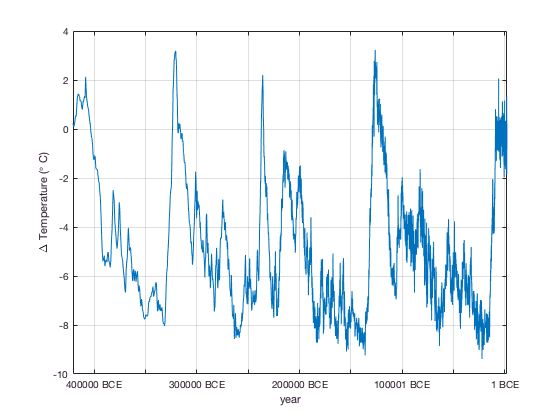

figure
plot(deut.year,deut.deltaTS);
xlabel('year');
ylabel('\Delta Temperature (\circ C)');
grid on

Now on to some control flow stuff

for i = 1:10
    m2 = mod(i,2) == 0;
    m3 = mod(i,3) == 0;
    if m2; disp([num2str(i) ' is a multiple of 2']); end
    if m3; disp([num2str(i) ' is a multiple of 3']); end
    if ~m2 && ~m3;  disp([num2str(i) ' is not a multiple of anything']); end
end

1 is not a multiple of anything


2 is a multiple of 2


3 is a multiple of 3


4 is a multiple of 2


5 is not a multiple of anything


6 is a multiple of 2


6 is a multiple of 3


7 is not a multiple of anything


8 is a multiple of 2


9 is a multiple of 3


10 is a multiple of 2


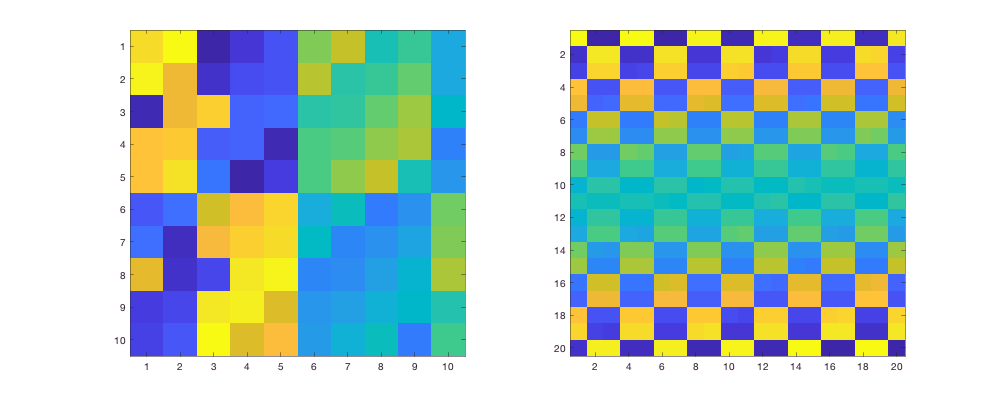



% A deterministic algorithm
figure('rend', 'painters', 'pos', [5 10 1000 400])
subplot(1,2,1)
imagesc(magic(10));
subplot(1,2,2)
imagesc(magic(20))   